# Crashcourse in Matlab - Part III: Plotting

One of the benefits of programing Matlab over C++ or Fortran is the ease of plotting and visualizing your computational results. Matlab plotting capabilities are vast and here we just cover the basics or at least some things I found useful.

clear all, close all
col = marc_colors();

## Figure windows

Unlike the live-scripts I uses for class demonstration, notmal scripts and functions will open figures in separate windows. I have found it useful to be able to control the basic features of these windows. 

h1 = figure('name','Marc''s most favorite plot')
set(gcf,'Visible','on') % This line is only necessary in live-scripts
h2 = figure('name','Marc''s second favorite plot')
set(gcf,'Visible','on') % This line is only necessary in live-scripts

The function [figure()](https://www.mathworks.com/help/matlab/ref/figure.html) opens an empty figure window and returns an object handle. The main use of the handle is that it can later be used to access the figure to add to it. For example, currently the second figure is active, i.e., up front, and any plotting command would add to figure 2. The following command makes figure 1 the active figure

figure(h1)

Note that you don't have to give a figure a name or save its function handle!

For me it is anoying that the figures are on top of each other. Imagine you are visualizing simulation results in figure 1 and information about solver convergence in figure 2. So it would be nice to see both of them next to each other. The function figure() can position the figure windows exactly, but first you need to know the size of your screen. The following code places the figures next to each other.

close all
scrsz = get(groot,'ScreenSize') % measure your screen size
h_l = figure('name','Left Figure','Position',[1 scrsz(4) scrsz(3)/2 scrsz(4)/2])
set(gcf,'Visible','on') % This line is only necessary in live-scripts
h_r = figure('name','Right Figure','Position',[scrsz(3)/2 scrsz(4) scrsz(3)/2 scrsz(4)/2])
set(gcf,'Visible','on') % This line is only necessary in live-scripts

Here the argument 'position' has following 4 entries [left-edge bottom-edge width height]. All the measurements need to be relative to the size of your screen.  

## Graphs

The standard 2D plotting functions are:

- [plot()](https://www.mathworks.com/help/matlab/ref/plot.html): both axes normal

- [loglog()](https://www.mathworks.com/help/matlab/ref/loglog.html): both axes logarithmic

- [semilogx()](https://www.mathworks.com/help/matlab/ref/semilogx.html): x-axis logarithmic and y-axis normal

- [semilogy()](https://www.mathworks.com/help/matlab/ref/semilogy.html): x-axis normal and y-axis logarithmic

For example we can plot everybodies favorite the error function and its buddy the complementary error function.

x = linspace(-5,5,1e2);
figure(h_l)
plot(x,erf(x)), xlabel('x'), ylabel 'erf'
figure(h_r)
plot(x,erfc(x)), xlabel 'x', ylabel 'erfc'

Here the functions [xlabel()](https://www.mathworks.com/help/matlab/ref/xlabel.html) and [ylabel()](https://www.mathworks.com/help/matlab/ref/ylabel.html) can be called without parentheses if you don't want any fancy options. The standard figure looks a bit faint on screen, so we'll generally make the defaults a bit stronger and try again.

close all
set(0, ...
    'defaultaxesfontsize',   18, ...
    'defaultaxeslinewidth',   2.0, ...
    'defaultlinelinewidth',   2.0, ...
    'defaultpatchlinewidth',  2.0,...
    'DefaultLineMarkerSize', 12.0);

h_l = figure('name','Left Figure','Position',[1 scrsz(4) scrsz(3)/2 scrsz(4)/2])
set(gcf,'Visible','on') % This line is only necessary in live-scripts
plot(x,erf(x))

h_r = figure('name','Right Figure','Position',[scrsz(3)/2 scrsz(4) scrsz(3)/2 scrsz(4)/2])
set(gcf,'Visible','on') % This line is only necessary in live-scripts
plot(x,erfc(x))

## Plotting multiple items in same plot

Often we would like to plot multiple things in the same plot, say some discrete data that magically fit some analytic theory. In the fimplest case this can be done by adding two data sets to the [plot](https://www.mathworks.com/help/matlab/ref/plot.html)() function.

x_data = linspace(-5,5,15);
y_data = sech(x_data)+5e-2*rand(size(x_data)); % add some noise
x_theory = linspace(-5,5,1e3);
y_theory = sech(x_theory);
figure
plot(x_theory,y_theory,'-',x_data,y_data,'o')
pbaspect([1 .8 1])

However, typically we would like to modify the graphs a bit and in that case you have to use individual plot commands and the [hold](https://www.mathworks.com/help/matlab/ref/hold.html)() command. For example I like it if the cirlces are filled white, so the marker covers the line if it is on top of it. This can be done as follows

h_nice = figure('name','Can I have my PhD now!') % subliminal message to advisor!
set(gcf,'Visible','on') % This line is only necessary in live-scripts
plot(x_theory,y_theory,'-','linestyle','-'), hold on
plot(x_data,y_data,'o','markerfacecolor','w'), hold off
title('Marc''s great experiments' ) % a bit more in your face
legend('my theory','my data')

Notice the difference between naming the figure window and giving the plot a title, using the [title](https://www.mathworks.com/help/matlab/ref/title.html)() function. Not surprisingly the [legend](https://www.mathworks.com/help/matlab/ref/legend.html)() function does what it says.

[There are two kinds of peope](https://www.youtube.com/watch?v=l1711jiiRtM), those who know LaTeX and geochemists (paraphrasing Michael Manga). Those who aspire to become geophysicists can use[ LaTeX](https://www.latex-project.org/) to add badass mathematical labels as follo

xlabel('$\oint_{\partial\Omega} \left[\frac{\sin(x)}{1-cos^2(x)}\right]\mathrm{d}x$','Interpreter','latex')
ylabel('$\sum_{n=1}^N \sum_{m=1}^M \int_{\Omega}\varphi_n(x)\varphi_m(x)\mathrm{d}x$','Interpreter','latex')

## Subplots

In many cases it is useful to be able to plot multiple separate plots in the same figure window. The function [subplot](https://www.mathworks.com/help/matlab/ref/subplot.html)() gladly accomplished this for you. 

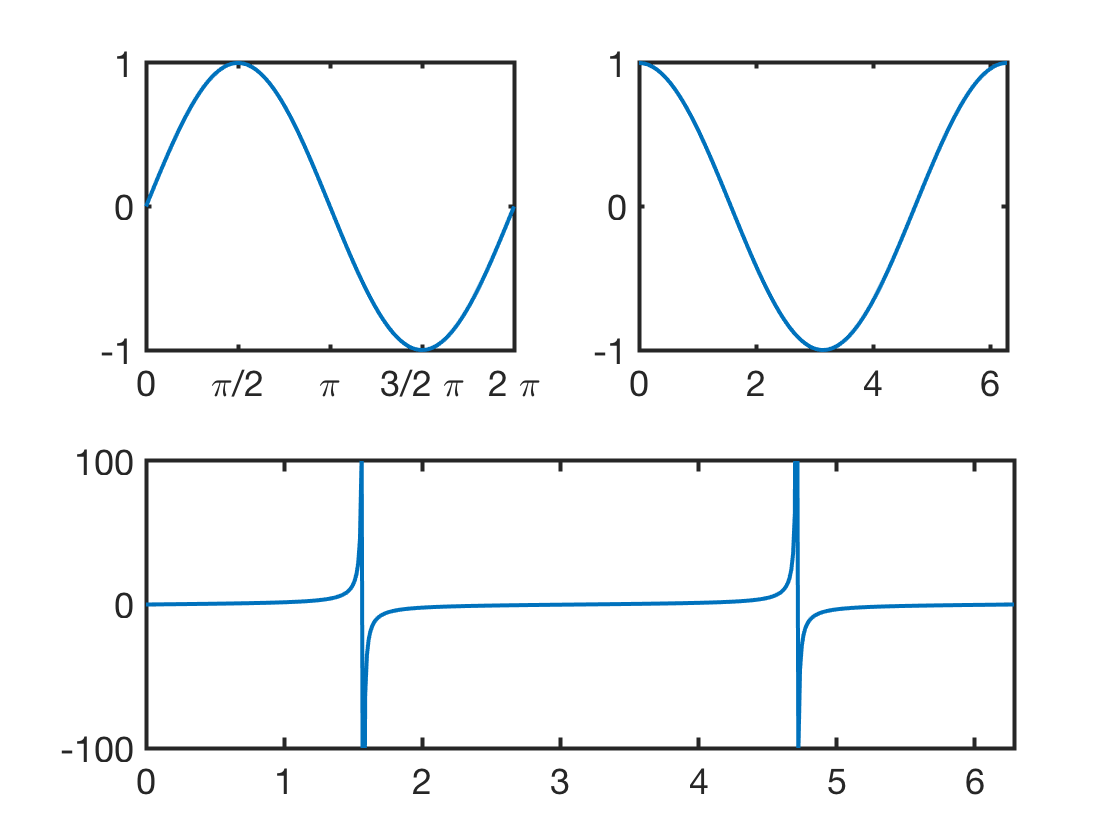

x = linspace(0,2*pi,5e2);
figure
subplot(2,2,1)
plot(x,sin(x))
xlim([0 2*pi])
set(gca,'xtick',[0:pi/2:2*pi],'xticklabel',{'0','\pi/2','\pi','3/2 \pi','2 \pi'})

subplot(2,2,2)
plot(x,cos(x))
xlim([0 2*pi])

subplot(2,2,[3 4])
plot(x,tan(x))
xlim([0 2*pi]), ylim([-100 100])

As you can see you can index the position of a plot similar to the elements of a 2D array/matrix, yey. 

However, sometimes subplots lead to ugly aspect ratios

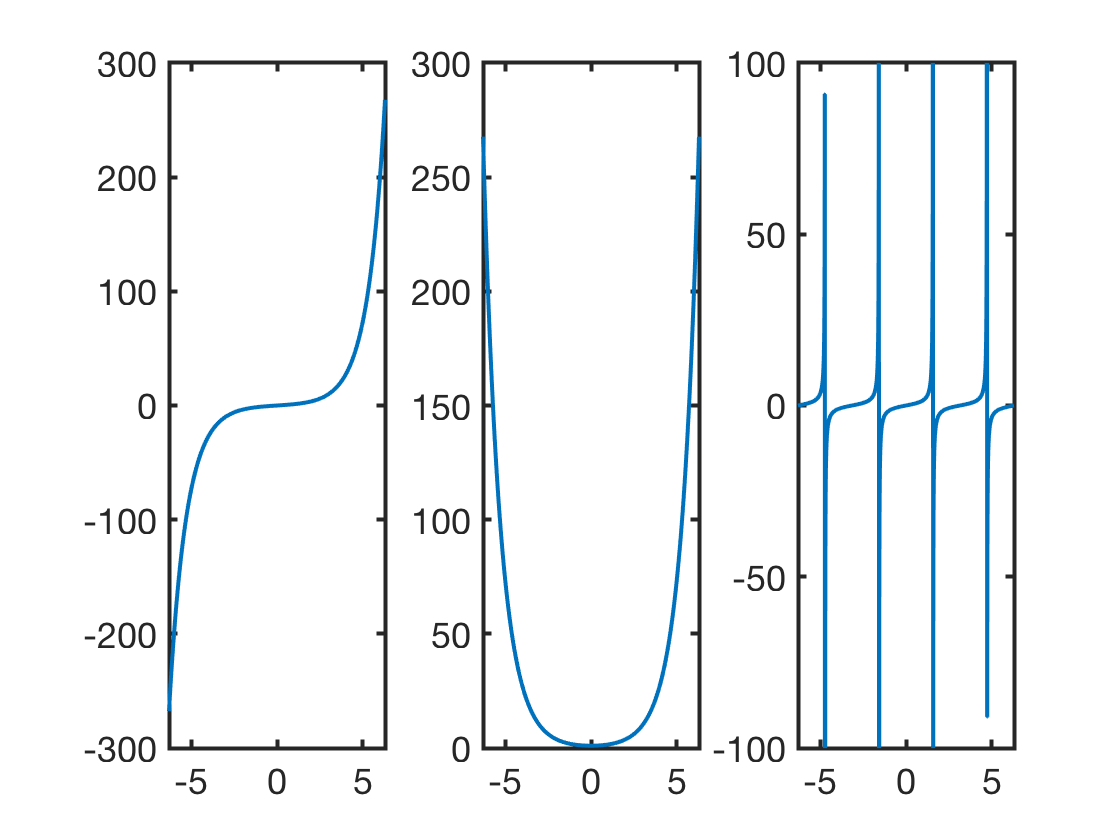

x = linspace(-2*pi,2*pi,1e3);
figure
subplot 131
plot(x,sinh(x))
xlim([-2*pi 2*pi])
subplot 132
plot(x,cosh(x))
xlim([-2*pi 2*pi])
subplot 133
plot(x,tan(x))
xlim([-2*pi 2*pi]), ylim([-100 100])

The slimplest fix to this is to prescribe the aspect ratio of the plots using the function [pbaspect](https://www.mathworks.com/help/matlab/ref/pbaspect.html)().

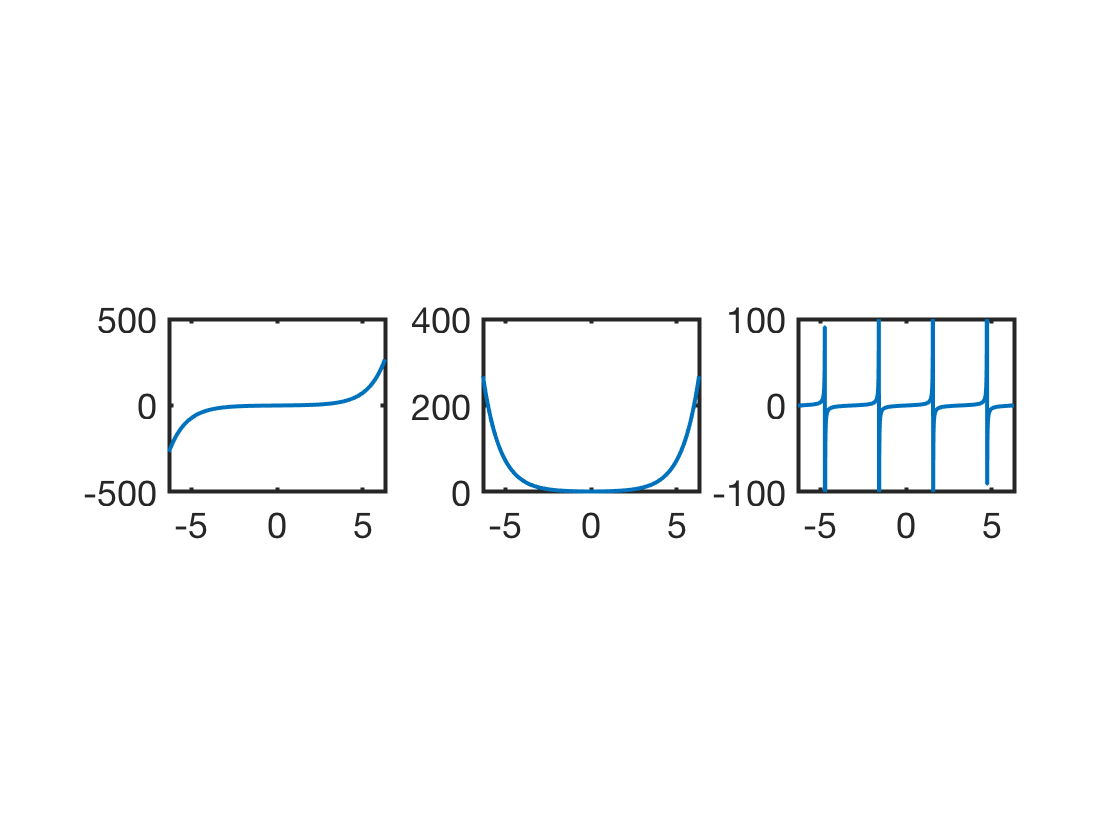

figure
subplot 131
plot(x,sinh(x))
xlim([-2*pi 2*pi])
pbaspect([1 .8 1])
subplot 132
plot(x,cosh(x))
xlim([-2*pi 2*pi])
pbaspect([1 .8 1])
subplot 133
plot(x,tan(x))
xlim([-2*pi 2*pi]), ylim([-100 100])
pbaspect([1 .8 1])

## Simple real-time animations

In many cases we would like tovisualize the simulation results while they are running. However, Matlab suprresses plotting until it is finished with its computations. You can force plotting with the function [drawnow](https://www.mathworks.com/help/matlab/ref/drawnow.html)().

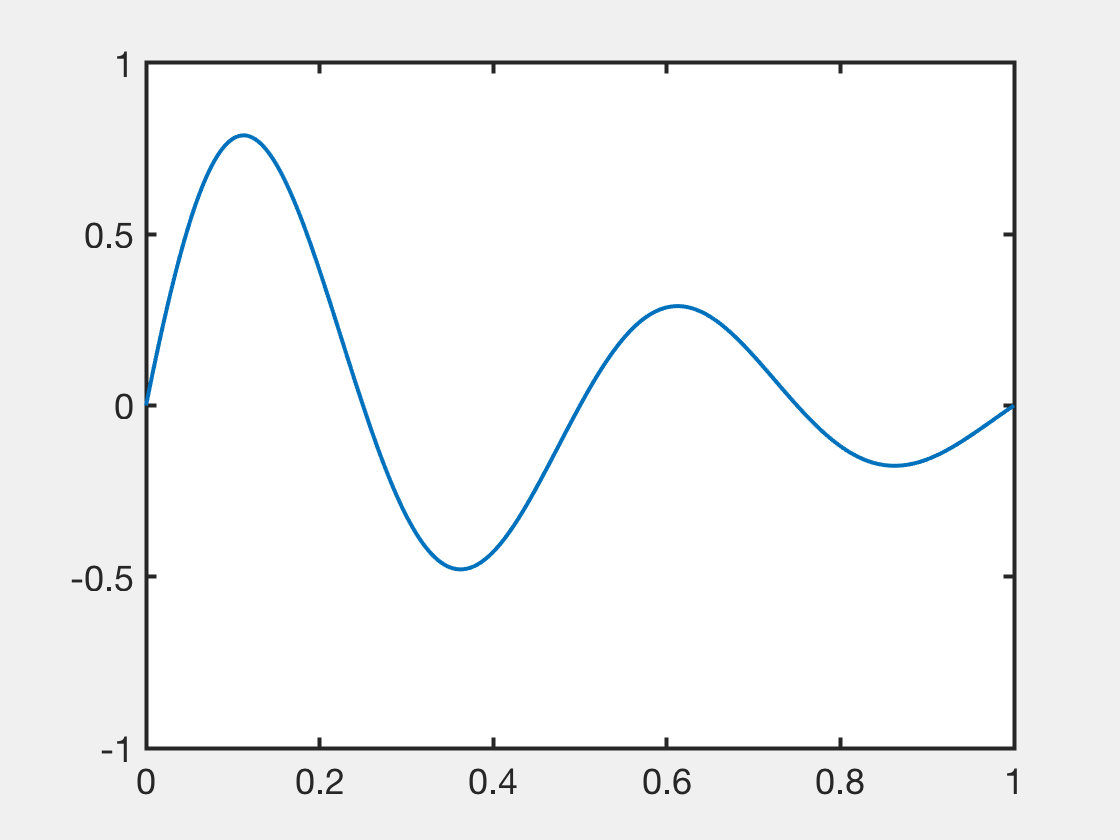

x = linspace(0,1,1e3);
velocity = pi;
time = linspace(0,1,1e2);
figure('name','I could watch this all day')
set(gcf,'Visible','on') % This line is only necessary in live-scripts

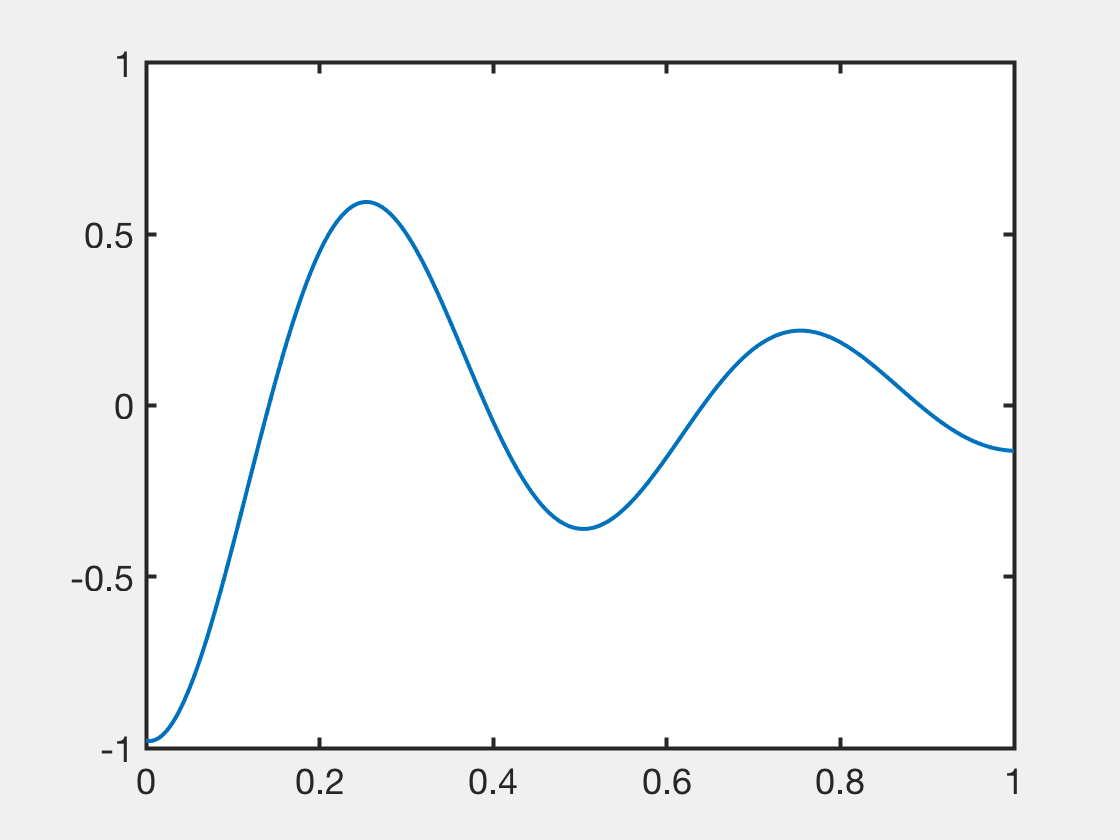


for n = 1:length(time)
    plot(x,sin(4*pi*(x-velocity*time(n))).*exp(-2*x))
    ylim([-1 1])
    drawnow
    pause(0.01)
end

The pause() function simply halts execution of the program for the specified number of seconds. Here its is necessary to slow down the speed of the animation. For any interesting simulation there will be no need to slow things down :-(.

## 2D Plotting Basics

Two-dimensional plotting functions in Matlab expect matrices for $x$, $y$ and $f(x,y)$. The function meshgrid() helpfully generates the  $X$ and $Y$ matrices from approriate $x$ and $y$ vectors.

x = 1:5; y = 1:3;
[X,Y] = meshgrid(x,y)

X =      1     2     3     4     5
     1     2     3     4     5
     1     2     3     4     5


Y =      1     1     1     1     1
     2     2     2     2     2
     3     3     3     3     3



x = linspace(-1,1,1e2); y = x; % vectors
[X,Y] = meshgrid(x,y);        % Matrices
F = sech(3*X).*cos(4*pi*Y);     % Some function

## Surface plots

Perhaps the most natural way to plot a 2D function is as a surface

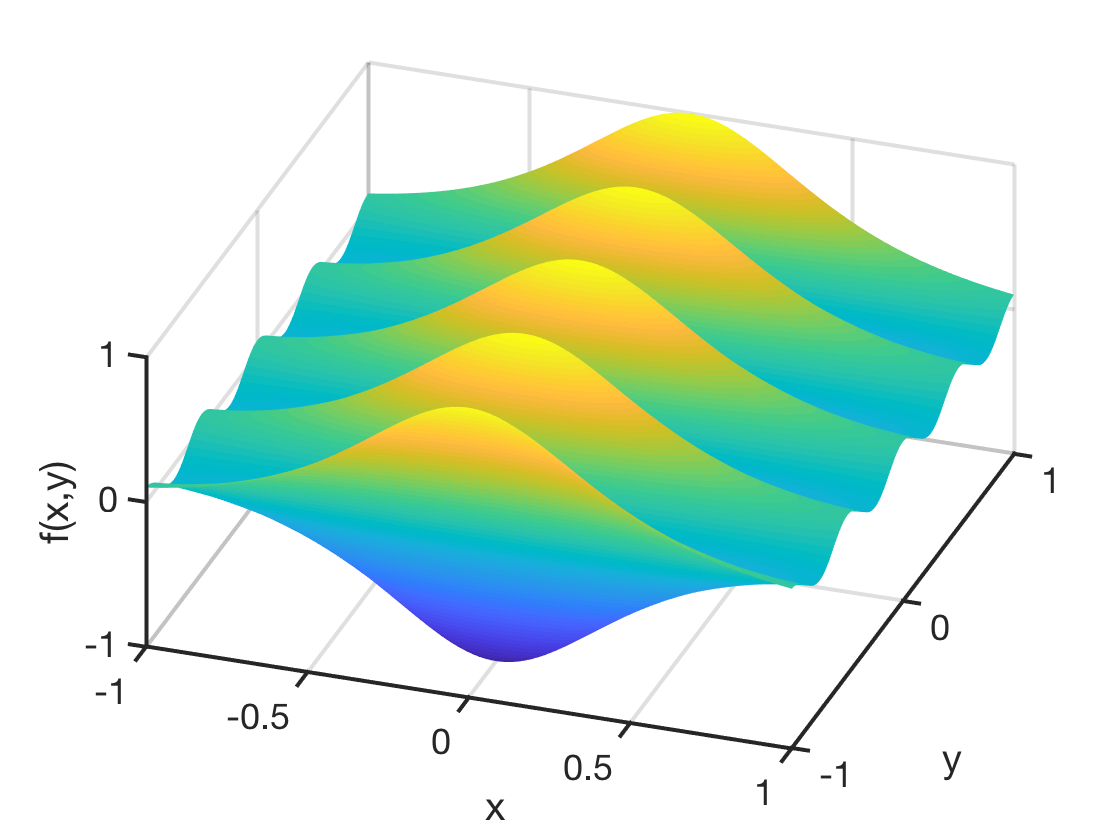

figure
% set(gcf,'Visible','on') % This line is only necessary in live-scripts

surf(X,Y,F)
shading('interp')
xlabel 'x', ylabel 'y', zlabel 'f(x,y)'
view(20,45)

Here the function [shading](https://www.mathworks.com/help/matlab/ref/shading.html)() gets rid of the ugly black lines and the function [view](https://www.mathworks.com/help/matlab/ref/view.html)() controls the orientation of the plot.

Sometimes it is useful to look at this plot directly from the top

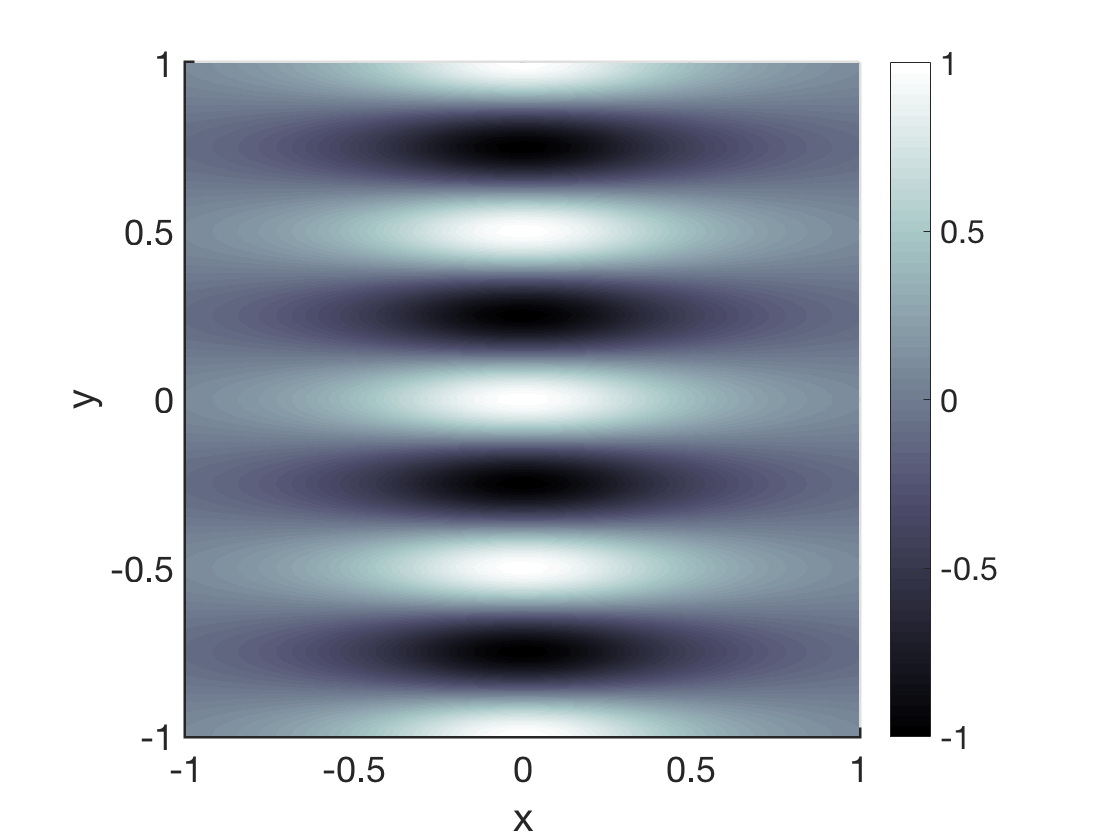

surf(X,Y,F)
shading('interp')
xlabel 'x', ylabel 'y'
view(2)
axis equal tight
colorbar
caxis([-1 1])

colormap('bone')

Here view(2) rotates the surface plot into the top-down view. The function [axis](https://www.mathworks.com/help/matlab/ref/axis.html)() controls the axis limits and aspect ratio. In this view it is useful to have a colorbar, generated by the function [colorbar](https://www.mathworks.com/help/matlab/ref/colorbar.html)(). The function [caxis](https://www.mathworks.com/help/matlab/ref/caxis.html)() controls the upper and lower limits of the colorscale. Finally, you can specify one of several amazing color maps using the function [colormap](https://www.mathworks.com/help/matlab/ref/colormap.html)().

## Contour plots

Another way to visualize the function is to plots its contours, like a topographic map. The function for this is [contour](https://www.mathworks.com/help/matlab/ref/contour.html)().

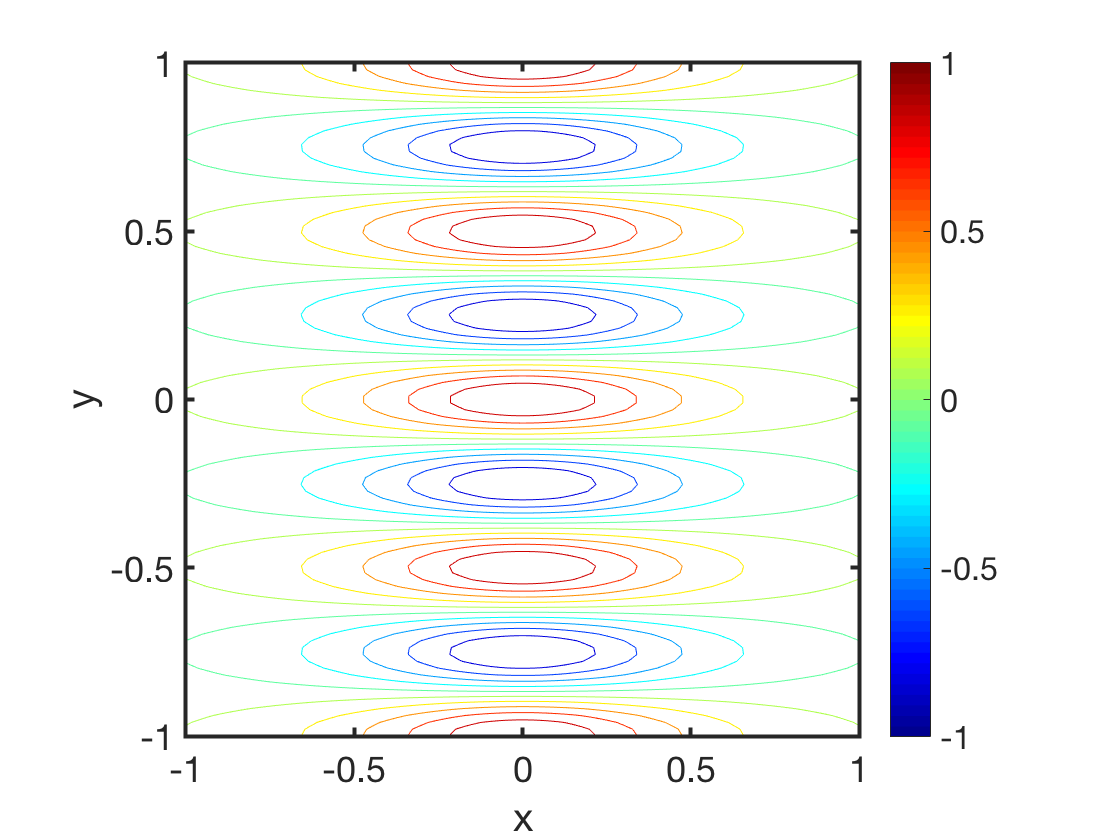

contour(X,Y,F,10)
xlabel 'x', ylabel 'y'
axis equal
colorbar
caxis([-1 1])
colormap('jet')

Choose colormap 'jet' for the vintage Matlab look from the 90's. Here we have specified to plot 10 contours, but you can also give a vector with specific values to plot. If you want to plot contours corresponding to a single value, you have to pass a vector that repeats that number twice - watch ... 

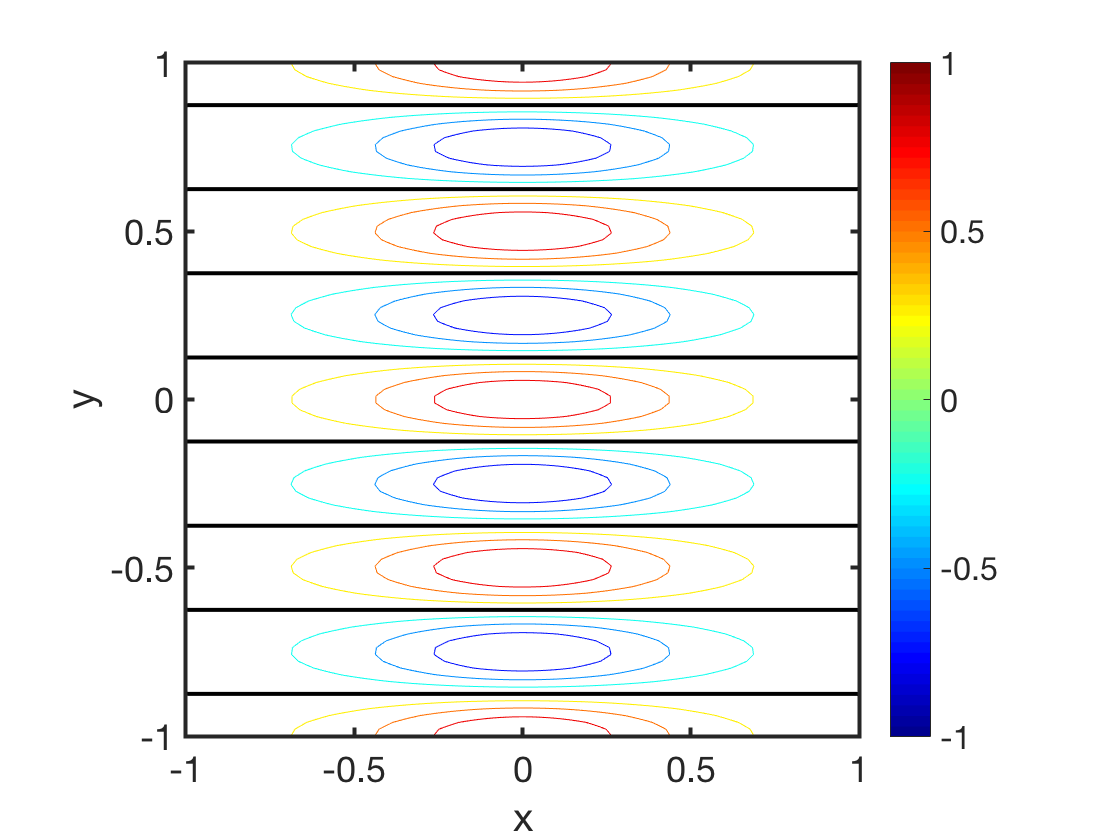

contour(X,Y,F,[-1:.25:1]), hold on
contour(X,Y,F,[0 0],'linewidth',2,'color','k')
xlabel 'x', ylabel 'y'
axis equal
colorbar
caxis([-1 1])

colormap('jet')